# 非線形モデル予測制御によるセミアクティブダンパ制御

本例題ではセミアクティブダンパの振動制御について非線形モデル予測制御（NMPC）を用いた設計方法について示す。

セミアクティブダンパは以下のようなマス・ばね・ダンパ系においてダンパの減衰係数を調整することで振動を抑制するシステムである。

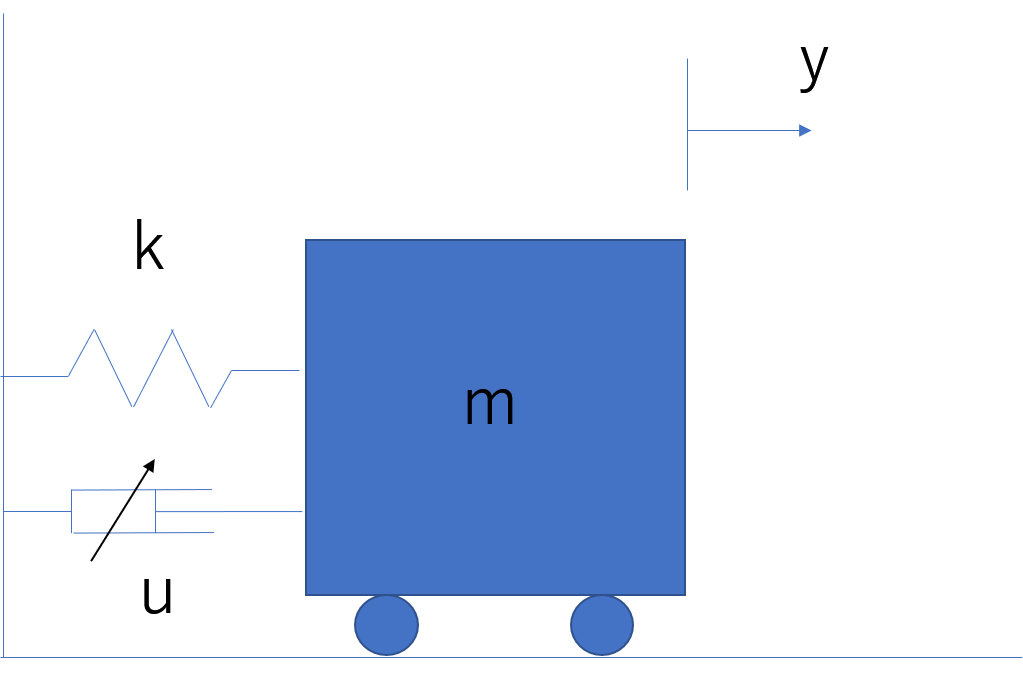

図1　セミアクティブダンパ（引用：実時間最適化による制御の実応用　大塚敏之著）

システムのダイナミクスは以下の通りである。


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \left(t\right)\\
{\dot{x} }_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \left(t\right)\\
-\frac{1}{m}\left(kx_1 \left(t\right)+x_2 \left(t\right)u\left(t\right)\right)
\end{array}\right\rbrack$$


状態量$x={\left\lbrack x_1 \;x_2 \right\rbrack }^T ={\left\lbrack y\;\dot{y} \right\rbrack }^T$である。

操作量として、減衰係数には上下限制約として以下を設ける。

$0\le u\le 1$, $-1\le \textrm{du}\le 1$

NMPCでは上記システムのダイナミクスに関する等式制約と上下限で構成される不等式制約の下で最適な操作量を求める。

なお、NMPCブロックではfminconコマンド※に実装されているSQP（逐次2次計画法）を用いて最適解を求めている。

そのため、実行スピードとしては期待出来るものではない（コンパイルしてmexを生成すれば、多少は改善する可能性はある）。

※使用するためにはOmitimization Toolboxが必要となる

clc,clear
open_system('semiAvtiveDamper.slx')

% Inital condition and reference value
ref = [0;0];
x0 = [2;0];
mv0 = 0;

MPC制御パラメーターを設定する。

nu = 1;     % Number of input
ny = 2;     % Number of output
nx = 2;     % Number of state
nd = 1;     % Number of disturbance
Ts = 0.1;   % Sampling time
params.stateFunction = 'stateFcn';          % State function
params.measurementFunction = 'measurement'; % Measurement function
params.Q = diag([50,10]);                   % Weight of output
params.R = 1;                               % Weight of input 
params.PredictiveHorizon = 10;
params.ControlHorizon = 5;
params.MV_min = 0;
params.MV_max = 1;
params.dMV_min = -1*Ts;
params.dMV_max = 1*Ts;
params.initialconditionMV = mv0;
params.initialconditionState = x0;
params.IterationMax = 50;

シミュレーションを実行する

Tsim = 20;
sim('semiAvtiveDamper',Tsim);